Clear all outputs and inputs and load the relevant data:

close all
%clear all
clc
%load('C:\Users\jacop\Uni Drive\Ing Matematica-2.0\FINTECH\Zenti\BusinessCase1\BankClients.mat')

## Preparing the data

First we divide the data into numerical and categorical and prepare them accordingly.

### `Numerical data`

`By taking a rapid look at the data (with a boxplot) we can easily see that the first two columns have a much wider range than all other columns. Indeed all other columns are already within the [0,1] range.`

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables;
boxplot(XNum) %plot all columns
boxplot(XNum(:,3:end)) %plot only columns from the third on

`We rescale only the first two numerical columns:`

for i = 1:size(XNum,2)
    XNum(i) = rescale(XNum(i)); % normalize in [0, 1]
end

### Categorical data

We create some dummy variables to deal with categorical data:

% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
end

We put the data back together:

X = [XCat XNum];

### Dataset inspection

By inspection we can see that the dataset is composed of a lot of observations.

nObservations = size(Data,1)

Therefore, to avoid to have our pc stuck in computational purgatory, we take a subsample:

nSubSample = 1500;
rng('shuffle') % we use the multi Fibonacci seed
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);

## Unsupervised Clustering

Since we have categorical data we can't apply the usual k-means algorithm since its mathematical foundations lose meaning on categorical spaces.

### Data exploring

We try a few distance options. First we explore a pure numerical distance funtion, the Mahalanobis distance:

rng('default') % for reproducibility
Y = tsne(X,'Algorithm','exact','Distance','mahalanobis');
subplot(2,2,1)
gscatter(Y(:,1),Y(:,2))
title('Mahalanobis')

As expected this distance doesn't give us a very good output since it is a numerical distance applied to categorical variables. We try to pass to the pure Euclidean distance:

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','euclidean');
subplot(2,2,2)
gscatter(Y(:,1),Y(:,2))
title('Euclidean')

>>>>>>>>This is, again, a Numerical distance amd thus gives us just as before very scattered data and no clusters can be easily identified. >>>> However, using the euclidean distance, which is still numerical, the output is not that scattered as in the previous case and, indeed, five clusters can be identified. This shows us how unreliable is applying a numerical distance to categorical data. 

Therefore we thought it best to pass to exploring a mixed distances. First we tried a mix of a Hamming distance for categorical data and Euclidean for numerical data and then swapped the former for a Jaccard distance:

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @HammingEuclidean);
subplot(2,2,3)
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Euclidean')
% rng('default') % for fair comparison
% Y = tsne(X,'Algorithm','exact','Distance', @JaccardEuclidean);
% subplot(2,2,4)
% gscatter(Y(:,1),Y(:,2))
% title('Mixed: Jaccard + Euclidean')

We observe that the Hamming-Euclidean mixed distance gives us very nice cluster, while the Jaccard-Euclidean distance fails because it reached the maximum number of iterations.

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @HammingEuclidean,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D Embedding')
view(-30,15)

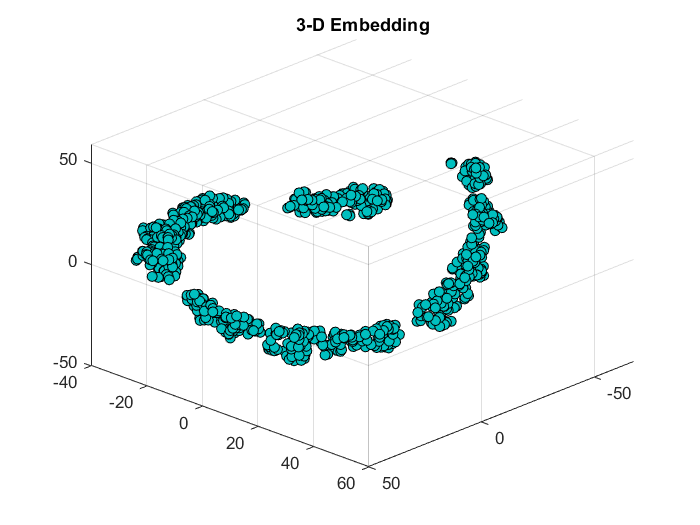

### **UMAP**

[reduction, umap, clusterIdentifiers, extras]=run_umap(X);

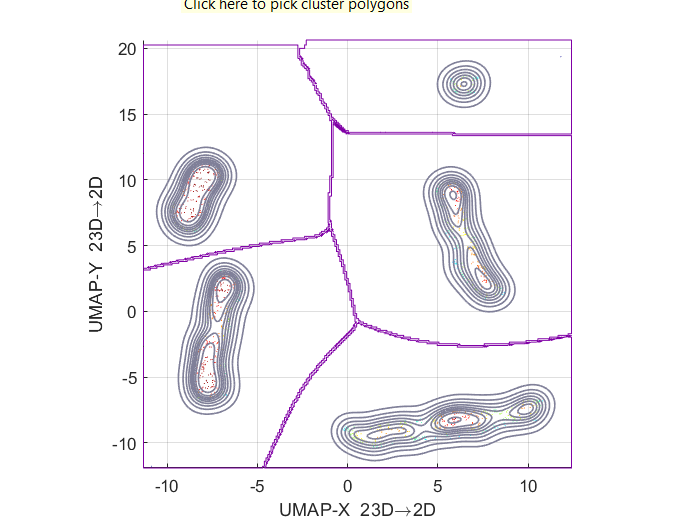

### Principal Components Analysis

We now use PCA to create new features to explain the output and we plot the loadings in order to understand which original features matter the most for each principal component. The variance is mostly explained by the first principal components which mostly depends on the 11-th feature.

[loadings,score,latent,~,var] = pca(X);
var
plot(1:size(X,2),loadings(:,1:3),'-')
xlabel('Variable');
ylabel('PCA Loading');
legend({'1st Component' '2nd Component' '3rd Component'},'location','NW');

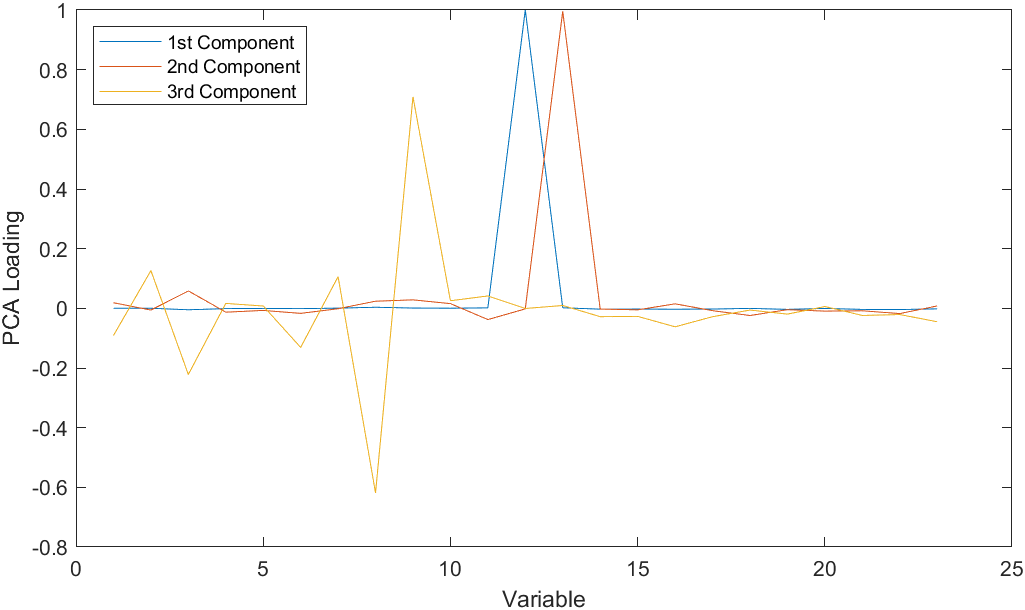

### K-Medoids clustering

As seen above we choose to create our cluster with the mixed Hamming-Euclidean distance. We need to take into account the fact that the medoids method doesn't always converge, so we have to run the algorithm a few times to obtain a meaningful result.

Furthermore, we tried out a few different values for the hyperparameters k to see which best fit our data.

#### K=3

[IDX3, C3, SUMD3, D3, MIDX3, INFO3] = kmedoids(X,3,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX3==1,1),Y(IDX3==1,2),Y(IDX3==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX3==2,1),Y(IDX3==2,2),Y(IDX3==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX3==3,1),Y(IDX3==3,2),Y(IDX3==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('3-D Embedding of 3 clusters')
legend
hold off

#### K=4

[IDX4, C4, SUMD4, D4, MIDX4, INFO4] = kmedoids(X,4,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX4==1,1),Y(IDX4==1,2),Y(IDX4==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX4==2,1),Y(IDX4==2,2),Y(IDX4==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX4==3,1),Y(IDX4==3,2),Y(IDX4==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX4==4,1),Y(IDX4==4,2),Y(IDX4==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
title('3-D Embedding of 4 clusters')
hold off
legend

#### K=5

[IDX5, C5, SUMD5, D5, MIDX5, INFO5] = kmedoids(X,5,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX5==1,1),Y(IDX5==1,2),Y(IDX5==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX5==2,1),Y(IDX5==2,2),Y(IDX5==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX5==3,1),Y(IDX5==3,2),Y(IDX5==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX5==4,1),Y(IDX5==4,2),Y(IDX5==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX5==5,1),Y(IDX5==5,2),Y(IDX5==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
title('3-D Embedding of 5 clusters')
hold off
legend

#### K=6

[IDX6, C6, SUMD6, D6, MIDX6, INFO6] = kmedoids(X,6,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX6==1,1),Y(IDX6==1,2),Y(IDX6==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX6==2,1),Y(IDX6==2,2),Y(IDX6==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX6==3,1),Y(IDX6==3,2),Y(IDX6==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX6==4,1),Y(IDX6==4,2),Y(IDX6==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX6==5,1),Y(IDX6==5,2),Y(IDX6==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(IDX6==6,1),Y(IDX6==6,2),Y(IDX6==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
title('3-D Embedding of 6 clusters')
legend
hold off


**K = 7**

[IDX7, C7, SUMD7, D7, MIDX7, INFO7] = kmedoids(X,7,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX7==1,1),Y(IDX7==1,2),Y(IDX7==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX7==2,1),Y(IDX7==2,2),Y(IDX7==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX7==3,1),Y(IDX7==3,2),Y(IDX7==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX7==4,1),Y(IDX7==4,2),Y(IDX7==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX7==5,1),Y(IDX7==5,2),Y(IDX7==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(IDX7==6,1),Y(IDX7==6,2),Y(IDX7==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
scatter3(Y(IDX7==7,1),Y(IDX7==7,2),Y(IDX7==7,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4700 0.9852 0.5160])
title('3-D Embedding of 7 clusters')
legend
hold off

### Clustering evaluation

We now pass to evaluate the clusters found above.

**Calinski-Harabasz criterion**

clust = [IDX3 IDX4 IDX5 IDX6 IDX7];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)

Here we have to take the highest value of the plot which corresponds to the value k=6.

**Silhouette criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html](https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html)).

eva3 = evalclusters(X,clust,'silhouette', 'Distance', @HammingEuclidean);
figure
plot(eva3)
eva3

Here the highest value corresponds to the value k=3.

**Dunn's criterion **

D = pdist(X);
D = squareform(D);
intercldist = max(D(IDX3 ~= IDX3')); % with euclidean distance 
intracldist = zeros(max(IDX3),1);
for i = 1:max(IDX3)
    intracldist(i) = mean(D(IDX3 == i, IDX3 == i), 'all')
end
Dunn3 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX4 ~= IDX4')); % with euclidean distance 
intracldist = zeros(max(IDX4),1);
for i = 1:max(IDX4)
    intracldist(i) = mean(D(IDX4 == i, IDX4 == i), 'all')
end
Dunn4 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX5 ~= IDX5')); % with euclidean distance 
intracldist = zeros(max(IDX5),1);
for i = 1:max(IDX5)
    intracldist(i) = mean(D(IDX5 == i, IDX5 == i), 'all')
end
Dunn5 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX6 ~= IDX6')); % with euclidean distance 
intracldist = zeros(max(IDX6),1);
for i = 1:max(IDX6)
    intracldist(i) = mean(D(IDX6 == i, IDX6 == i), 'all')
end
Dunn6 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX7 ~= IDX7')); % with euclidean distance 
intracldist = zeros(max(IDX7),1);
for i = 1:max(IDX7)
    intracldist(i) = mean(D(IDX7 == i, IDX7 == i), 'all')
end
Dunn7 = min(intercldist)/max(intracldist);

**DB-Scan**

We now apply DBSCAN, a method which does not require to know the number of clusters a priori. A point belongs to a cluster if it is close to many points from that cluster. 

minpts = 100; % we should have 28 features, but we select 100 in order not to have too small clusters
Distance = HammingEuclidean(X,X);
orderedDistance = sort(Distance, 'ascend');
figure
plot(sort(orderedDistance(minpts,:)))
epsilon = 3.19;
[DBSCANidx, corepts] = dbscan(Distance,epsilon,minpts,'Distance','precomputed');
nDBSCANCluster = unique(DBSCANidx)

Count the number of noise points:

numNoisePoints = sum(DBSCANidx == -1)

We have tried with different values of epsilon and checked that the number of noise points decreases and it detects more cluster as we approach epsilon == 3.19.

So we find 4 clusters and one group of outliers. We plot clusters in 2-D:

Y = tsne(X,'Algorithm','exact','Distance', @HammingEuclidean,'NumDimensions', 2);
figure
for i = 1:size(nDBSCANCluster,1)
    pointer = nDBSCANCluster(i);
    scatter(Y(DBSCANidx==pointer,1),Y(DBSCANidx==pointer,2),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colours
    hold on
end
title('2-D t-SNE embedding of DBSCAN clusters')
legend
hold off

[Inserire figura]

While in 3-D:

Y = tsne(X,'Algorithm','exact','Distance', @HammingEuclidean,'NumDimensions',3);
figure
for i = 1:size(nDBSCANCluster,1)
    pointer = nDBSCANCluster(i);
    scatter3(Y(DBSCANidx==pointer,1),Y(DBSCANidx==pointer,2),Y(DBSCANidx==pointer,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colors
    hold on
end
hold off
legend

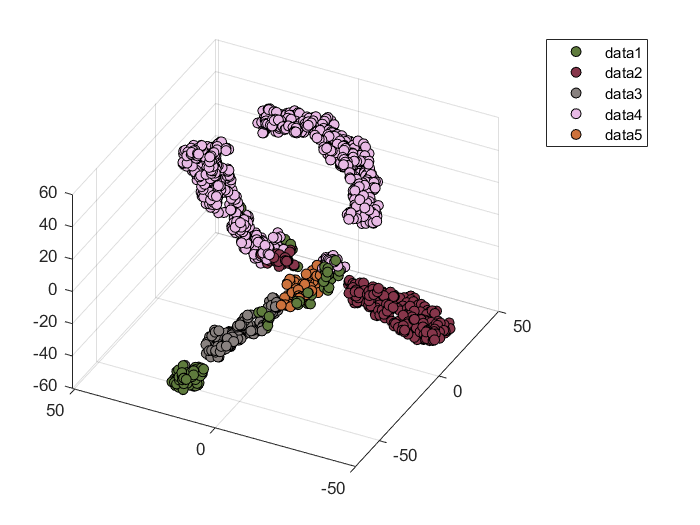

**Spectral clustering**

Distance = HammingEuclidean(X,X);
Similarity = exp(-Distance.^2); % kernel transformation
issymmetric(Similarity); % check symmetry
nCluster = 4;
[SpectralIdx, V, D] = spectralcluster(Similarity,nCluster,'Distance','precomputed','LaplacianNormalization','symmetric');
figure
bar(D)
title('Eigenvalues')
figure
for i = 1:nCluster
    scatter3(Y(SpectralIdx==i,1),Y(SpectralIdx==i,2),Y(SpectralIdx==i,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colors
    hold on
end
title('3-D Embedding of 5 clusters')
hold off
legend

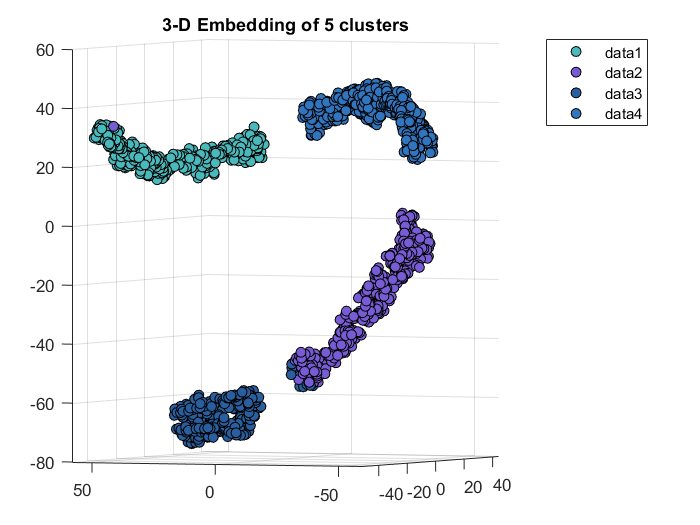

Spectral is better 